clear
clc
close all

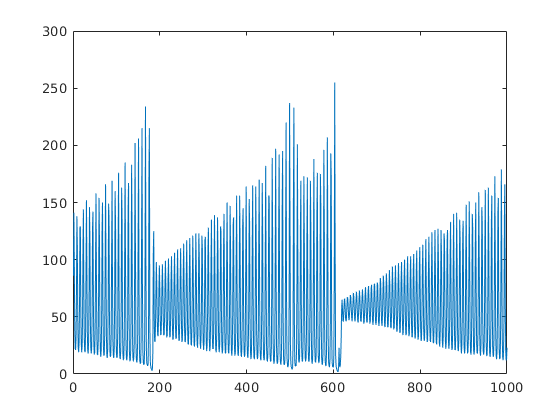

% Reading in the training data and converting it to an Nx1 array
lasertrain = readtable("lasertrain.dat");
lasertrain(:,1:3) = [];
lasertrain = table2array(lasertrain);
plot(lasertrain)

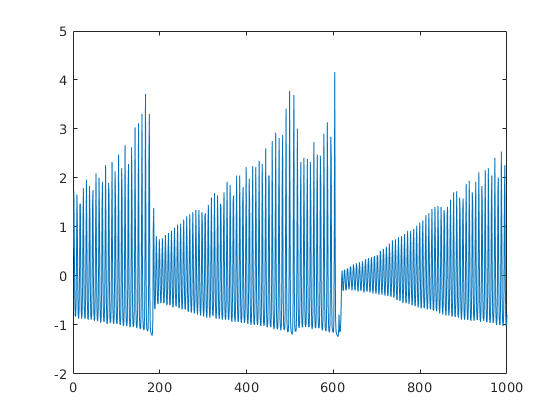

% Standardising the data to have zero mean and unit variance
mu_train = mean(lasertrain);
sig_train = std(lasertrain);
lasertrain_standardised = (lasertrain - mu_train) / sig_train;
plot(lasertrain_standardised);

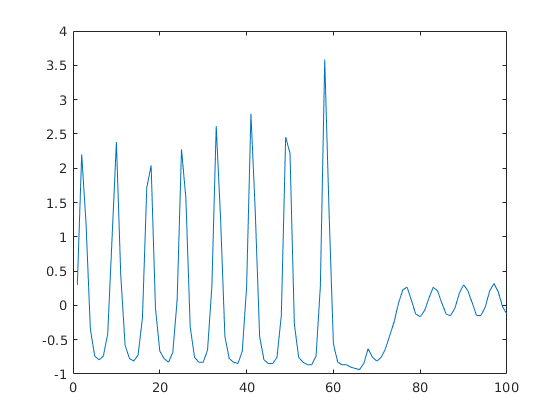

% Reading in the prediction data and converting it to an Nx1 array
lasertest = readtable("laserpred.dat");
lasertest(:,1:3) = [];
lasertest = table2array(lasertest);

% Standardising the test data to have zero mean and unit variance
mu_test = mean(lasertest);
sig_test = std(lasertest);
lasertest_standardised = (lasertest - mu_test) / sig_test;
plot(lasertest_standardised);

[training, target_train] = getTimeSeriesTrainData(lasertrain_standardised, 20)

training =     0.5569    1.7302    0.7489   -0.4031   -0.8084   -0.8297   -0.5951    0.2583    1.6662    1.0903   -0.2537   -0.7871   -0.8724   -0.7017   -0.0191    1.4742    1.4742   -0.0404   -0.7017   -0.8724   -0.7657   -0.2964    1.1116    1.7942    0.2796   -0.6377   -0.8511   -0.8724   -0.4884    0.6849    1.9649    0.7063   -0.5097   -0.8511   -0.8937   -0.6591    0.2369    1.8369    1.2183   -0.2964   -0.7871   -0.8937   -0.8084   -0.1684    1.4529    1.7516    0.0449   -0.7231   -0.9151   -0.8724
    1.7302    0.7489   -0.4031   -0.8084   -0.8297   -0.5951    0.2583    1.6662    1.0903   -0.2537   -0.7871   -0.8724   -0.7017   -0.0191    1.4742    1.4742   -0.0404   -0.7017   -0.8724   -0.7657   -0.2964    1.1116    1.7942    0.2796   -0.6377   -0.8511   -0.8724   -0.4884    0.6849    1.9649    0.7063   -0.5097   -0.8511   -0.8937   -0.6591    0.2369    1.8369    1.2183   -0.2964   -0.7871   -0.8937   -0.8084   -0.1684    1.4529    1.7516    0.0449   -0.7231   -0.9151   -0.87

target_train =    -0.7657   -0.2964    1.1116    1.7942    0.2796   -0.6377   -0.8511   -0.8724   -0.4884    0.6849    1.9649    0.7063   -0.5097   -0.8511   -0.8937   -0.6591    0.2369    1.8369    1.2183   -0.2964   -0.7871   -0.8937   -0.8084   -0.1684    1.4529    1.7516    0.0449   -0.7231   -0.9151   -0.8724   -0.4884    0.8556    2.0929    0.5569   -0.5951   -0.9151   -0.9151   -0.7017    0.2583    2.0076    1.2396   -0.3604   -0.8511   -0.9577   -0.8297   -0.2751    1.4529    1.9222    0.0663   -0.7657


% Getting target and training data with lag
max_lag = 20;
errors = zeros(60);

for i=1:max_lag
    
    [training, target_train] = getTimeSeriesTrainData(lasertrain_standardised, i);
    
    % Formatting training data for train function
    train_set = cell(i,1);
    
    for j=1:i
        train_set{j,1} = training(j,:);
    end
    
    % Configuring and training the network
    layers = [50];
    net = feedforwardnet(layers, 'trainbr');
    net.numInputs = i;
    net.trainParam.epochs = 20;
    net.divideFcn = 'dividerand';
    %net.divideParam.trainRatio = 0.7;
    %net.divideParam.valRatio = 0.15;
    %net.divideParam.testRatio = 0.15;
    %net.trainParam.max_fail = 100;
    for j=1:i
        net.inputs{j}.size = 1;
        net.inputConnect(1,j) = 1;
    end
    
    [net,tr] = train(net, train_set, target_train);
    
    % Getting target and test data with lag
    [test, target_predict] = getTimeSeriesTrainData(lasertest_standardised, i);
    
    prediction = zeros(1,100-i);
    x = test(:,1);
    
    for j=1:100-i
        y = net(x);
        prediction(1, j) = y;
        x = vertcat(x(2:end),y);
    end
    
    error = mean((prediction - target_predict).^2);
    errors(i) = error;
end

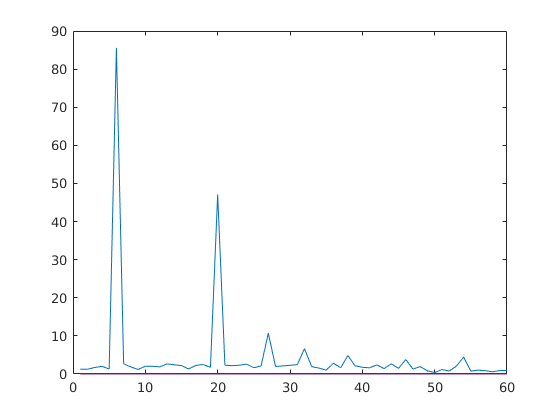

plot(errors)

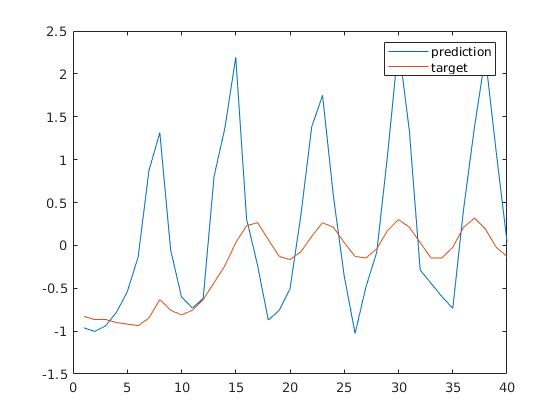

figure 
plot(prediction);
hold on;
plot(target_predict);
legend('prediction','target');
hold off;